# **Chaper 5:  Resampling Methods**

## **5.3 Lab: Cross-Validation and the Bootstrap**

### **5.3.1 The Validation Set Approach**

clear all; clc; close all;
Auto = readtable("Data\Auto.csv", 'TreatAsEmpty',{'?','NA','N/A'} );
Auto.name = categorical(Auto.name);

Remove missing entries

Auto = rmmissing(Auto,1);
rng(1);
train = randsample(392,196);

Set difference of two arrays = The indexs of the set test

test = setdiff((1:size(Auto,1)), train, 'stable').'; 

lmFit = fitlm(Auto(train,:), 'mpg ~ horsepower');

mean((Auto.mpg(test)-predict(lmFit,Auto(test,:))).^2)

ans = 22.4891

lmFit2 = fitlm(Auto(train,:), 'mpg ~ horsepower^2');
mean((Auto.mpg(test)-predict(lmFit2,Auto(test,:))).^2)

ans = 17.0342

lmFit3 = fitlm(Auto(train,:), 'mpg ~ horsepower^3');
mean((Auto.mpg(test)-predict(lmFit3,Auto(test,:))).^2)

ans = 16.9817

rng(2);
train = randsample(392,196);
test = setdiff((1:size(Auto,1)), train, 'stable').'; 
lmFit = fitlm(Auto(train,:), 'mpg ~ horsepower');
mean((Auto.mpg(test)-predict(lmFit,Auto(test,:))).^2)

ans = 22.7984

lmFit2 = fitlm(Auto(train,:), 'mpg ~ horsepower^2');
mean((Auto.mpg(test)-predict(lmFit2,Auto(test,:))).^2)

ans = 16.9337

lmFit3 = fitlm(Auto(train,:), 'mpg ~ horsepower^3');
mean((Auto.mpg(test)-predict(lmFit3,Auto(test,:))).^2)

ans = 16.9162

### **5.3.2 Leave-One-Out Cross-Validation**

glmFit = fitglm(Auto,'mpg ~ horsepower');
glmFit.Coefficients

ans = 2×4 table
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)      39.936       0.7175      55.66    1.2204e-187
    horsepower     -0.15784    0.0064455    -24.489      7.032e-81


lmFit = fitlm(Auto,'mpg ~ horsepower');
lmFit.Coefficients

ans = 2×4 table
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)      39.936       0.7175      55.66    1.2204e-187
    horsepower     -0.15784    0.0064455    -24.489      7.032e-81


cv = cvpartition(392,'LeaveOut');
yfit = @(Xtrain,ytrain,Xtest)(...
    predict(fitlm(Xtrain,ytrain),Xtest)...
    );
cvErr = crossval('mse',Auto.horsepower,Auto.mpg,'predfun',yfit,'partition',cv)

cvErr = 24.2315

% or
% cvErr = crossval('mse',Auto.horsepower,Auto.mpg,'predfun',yfit,'leaveout',1)

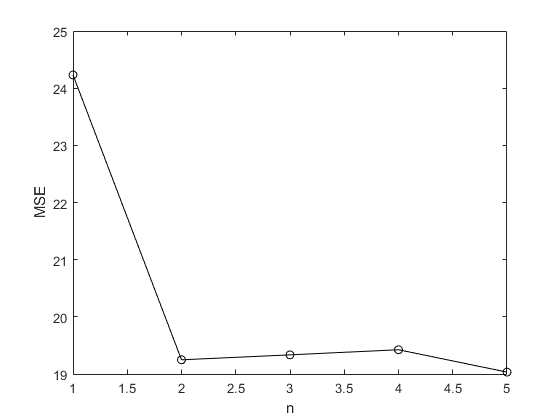

% Create a random partition for leave-one-out cross-validation on n observations
yfit=@(XTRAIN,ytrain,XTEST)(...
    XTEST*regress(ytrain,XTRAIN)...
    );
myFuncHandle = @myfunc;
for i = 1:5
    cvErr5(i) = crossval('mse',myFuncHandle(Auto.horsepower, i),Auto.mpg,'predfun',yfit,'leaveout',1);
end
plot(cvErr5,'Marker','o','Color','k');
xlabel('n'); ylabel('MSE');

### **5.3.3 k-Fold Cross-Validation**

rng(17);
for i = 1:10
    cvErr10(i) = crossval('mse',myFuncHandle(Auto.horsepower, i),Auto.mpg,'predfun',yfit,'kfold',10);
end

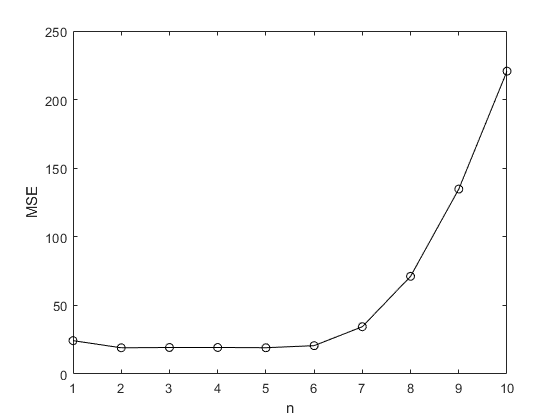

plot(cvErr10,'Marker','o','Color','k');
xlabel('n'); ylabel('MSE');

### **5.3.4 The Bootstrap**

**Estimating the Accuracy of a Statistic of Interest**

clear all; clc; close all;
Portfolio = readtable("Data\Portfolio.csv", 'TreatAsEmpty',{'?','NA','N/A'} );

Estimate $\alpha$ using all 100 observations based on applying (5.7)

anphaFN(Portfolio,(1:100))

ans = 0.5758

Randomly select 100 observations from the range 1 to 100, with replacement

rng(1);
% Random sample, with or without replacement
anphaFN(Portfolio,randsample(100,100,'true'))

ans = 0.5163

Produce 1000 bootstrap estimates for $\alpha$

fprintf('ORDINARY NONPARAMETRIC BOOTSTRAP');

ORDINARY NONPARAMETRIC BOOTSTRAP

bootfun1 = @anphaFN;
% Bootstrap sampling
[bootstat,bootsam] = bootstrp(1000,bootfun1,Portfolio,randsample(100,100,'true'));
array2table([mean(bootstat), std(bootstat)],...
    'VariableNames',{'original','StdError'}, 'RowNames',{'t1*'})

ans = 1×2 table
           original    StdError
           ________    ________

    t1*    0.58032     0.16749 


**Estimating the Accuracy of a Linear Regression Model**

clear all; clc; close all;
Auto = readtable("Data\Auto.csv", 'TreatAsEmpty',{'?','NA','N/A'} );
Auto.name = categorical(Auto.name);
Auto = rmmissing(Auto,1);

bootfun2 = @TableCoffLm;
bootfun2(Auto,(1:392))

ans = 2×1 table
                   Estimate
                   ________

    (Intercept)      39.936
    horsepower     -0.15784


rng(1);
bootfun2(Auto,randsample(392,392,'true'))

ans = 2×1 table
                   Estimate
                   ________

    (Intercept)      40.234
    horsepower     -0.15687


bootfun2(Auto,randsample(392,392,'true'))

ans = 2×1 table
                   Estimate
                   ________

    (Intercept)      40.476
    horsepower     -0.16134


Compute the standard errors of 1000 bootstrap estimates for the intercept and slope terms

bootfun3 = @coffLm;
bootstat = bootstrp(1000, bootfun3,Auto,randsample(392,392,'true'));
fprintf('Bootstrap Statistics:');

Bootstrap Statistics:

array2table([mean(bootstat)', std(bootstat)'],...
    'VariableNames',{'Original','StdError'}, 'RowNames',{'t1*','t2*'})

ans = 2×2 table
           Original    StdError
           ________    ________

    t1*      39.959      1.4166
    t2*    -0.15829    0.012264


Compute the bootstrap standard error estimates and the standard linear regression estimates that result from fitting the quadratic model to the data

bootfun4 = @coffLm2;
rng(1);
fprintf('ORDINARY NONPARAMETRIC BOOTSTRAP');

ORDINARY NONPARAMETRIC BOOTSTRAP

bootstat = bootstrp(1000, bootfun4,Auto,randsample(392,392,'true'));
fprintf('Bootstrap Statistics:');

Bootstrap Statistics:

array2table([mean(bootstat)', std(bootstat)'],...
    'VariableNames',{'Original','StdError'}, 'RowNames',{'Intercept','horsepower','horsepower^2'})

ans = 3×2 table
                    Original      StdError 
                    _________    __________

    Intercept          57.007        3.8005
    horsepower        -0.4684      0.061265
    horsepower^2    0.0012408    0.00022485


fprintf('SUMMARY Coefficients');

SUMMARY Coefficients

fitlm(Auto, 'mpg ~ horsepower + horsepower^2').Coefficients

ans = 3×4 table
                    Estimate         SE         tStat       pValue   
                    _________    __________    _______    ___________

    (Intercept)          56.9        1.8004     31.604    1.7409e-109
    horsepower       -0.46619      0.031125    -14.978     2.2894e-40
    horsepower^2    0.0012305    0.00012208      10.08     2.1963e-21


[Local functions](https://www.mathworks.com/help/matlab/ref/localfunctions.html) (Function handle), used in the main program

function y = myfunc(x, n) 
% The output of the function is of the form y = [1, x, x^2, ..., x^n]
    y = [ones(length(x), 1), x];
    if n>= 2
        for i = 2:n
            y = [y, x.^i];
        end
    end
end

function y = anphaFN(data, index) 
    % Calculate the alpha according to the formula (5.7) of the book "An Introduction to Statistical Learning with Applications in R"
    X = data.X(index);
    Y = data.Y(index);
    Cov = cov(X,Y);
    y = (var(Y) - Cov(1,2))/(var(X) + var(Y) - 2*Cov(1,2));
end

function y = TableCoffLm(data, index)
    % Create a table of linear regression coefficients
    lmFit = fitlm(data(index,:), 'mpg ~ horsepower');
    y = lmFit.Coefficients(:, 1);
end

function y = coffLm(data, index)
    % Calculate the linear regression coefficients
    lm = fitlm(data(index,:), 'mpg ~ horsepower');
    y = lm.Coefficients{:, 1};
end

function y = coffLm2(data, index)
    % Calculate the quadratic regression coefficients
    lm = fitlm(data(index,:), 'mpg ~ horsepower + horsepower^2');
    y = lm.Coefficients{:,1};
end